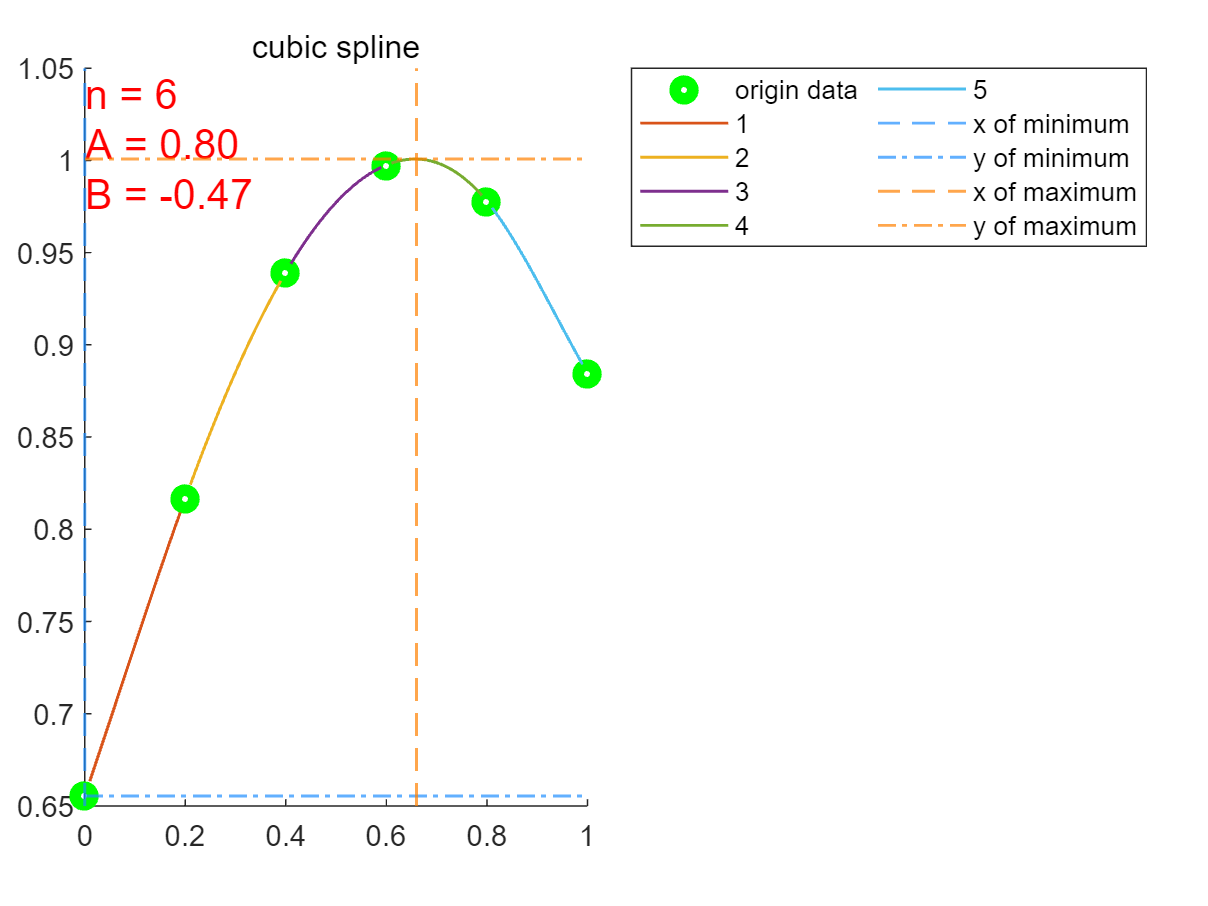

clc;clear;close all;
x0s = [0, 0.2, 0.4, 0.6, 0.8, 1];
fx0s = [0.6554, 0.8167, 0.9394, 0.9975, 0.9778, 0.8847];
boun_set = [1, 0.8, -0.47];
x = 0:0.01:1;

figure;
Pnx = polynomial_interpolation(x0s, fx0s, x, 3, boun_set);
[val_1, idx_1] = min(Pnx);
[val_2, idx_2] = max(Pnx);
xmin = x(idx_1);
ymin = val_1;
xmax = x(idx_2);
ymax = val_2;


hold on;
xline(xmin, '--', 'Color', [0.12, 0.56, 1], 'LineWidth', 1, 'DisplayName', 'x of minimum');
hold on;
yline(ymin, '-.', 'Color', [0.12, 0.56, 1], 'LineWidth', 1, 'DisplayName', 'y of minimum');

hold on;
xline(xmax, '--', 'Color', [1, 0.5, 0], 'LineWidth', 1, 'DisplayName', 'x of maximum');
hold on;
yline(ymax, '-.', 'Color', [1, 0.5, 0], 'LineWidth', 1, 'DisplayName', 'y of maximum');



fprintf("Estimated position of minimum is %f", xmin);

Estimated position of minimum is 0.000000

fprintf("Estimated minimum is %f", ymin);

Estimated minimum is 0.655400

fprintf("Estimated position of maximum is %f", xmax);

Estimated position of maximum is 0.660000

fprintf("Estimated maximum is %f", ymax);

Estimated maximum is 1.000729